% prepare an image with noise
im = imread('canoe.tif');
sigma=25;
noise = uint8(randn(size(im))).*sigma;
%im=im+noise;
disp('Image with noise')

Image with noise


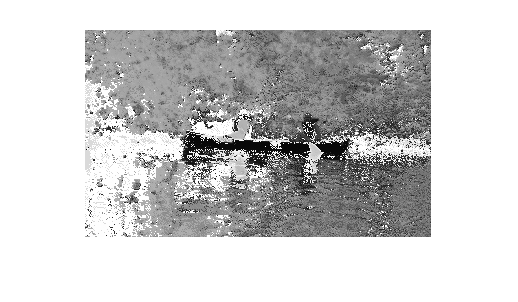

imshow(im)


% kernel size
hsize=31;
sigma=5;
% build a Gaussian filter
h=fspecial('gaussian',hsize,sigma);
disp('Gaussian function')

Gaussian function


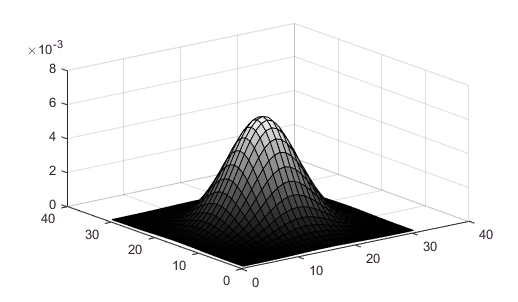

surf(h);

disp('Kernel')

Kernel


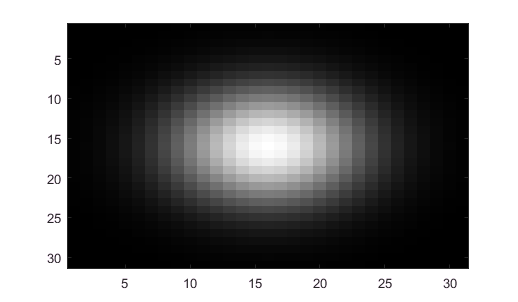

imagesc(h);

% aplly Gaussian filter to an image
outim=imfilter(im, h);
disp('Filtered image');

Filtered image


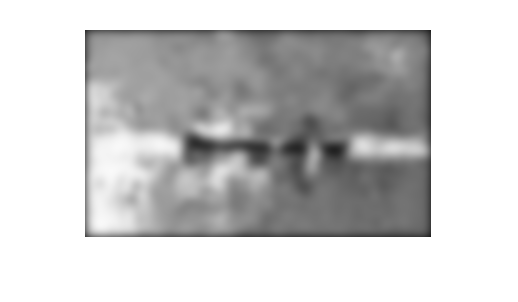

imshow(outim);    

**Remove noise with a Gaussian filter**

The bigger noise sigma is, the more noise will be.

The bigger filter sigma is, the blurrier image will be.

% Load an image (perfect)
img = imread('moon.tif');
disp('Original image');

Original image


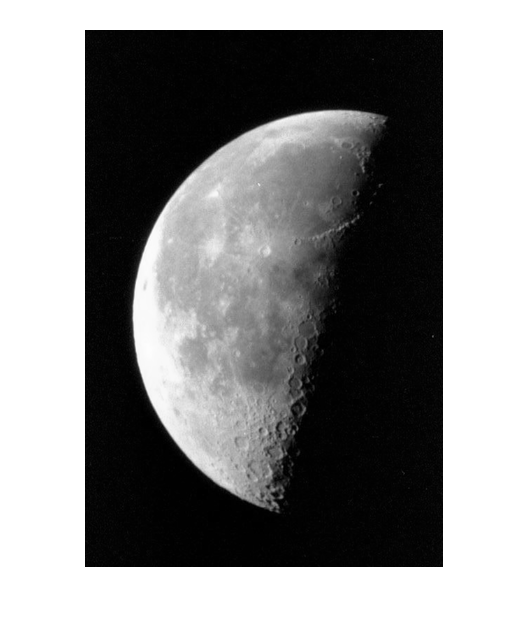

imshow(img);


% Add some noise
noise_sigma=25;
noise = uint8(randn(size(img))).*noise_sigma;
noisy_img=img+noise;
disp('noisy image');

noisy image


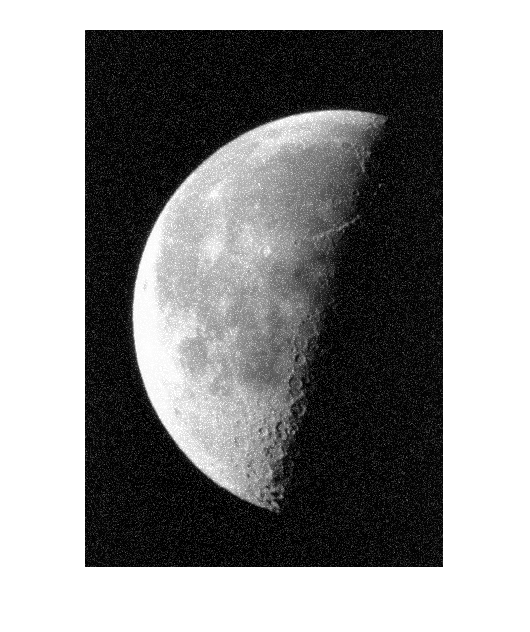

imshow(noisy_img);


% Create a Gaussian filter
filter_size=21;
filter_sigma=2;
filter = fspecial('gaussian',filter_size,filter_sigma);
% show filter info (not required)
disp('Gaussian filter:')

Gaussian filter:


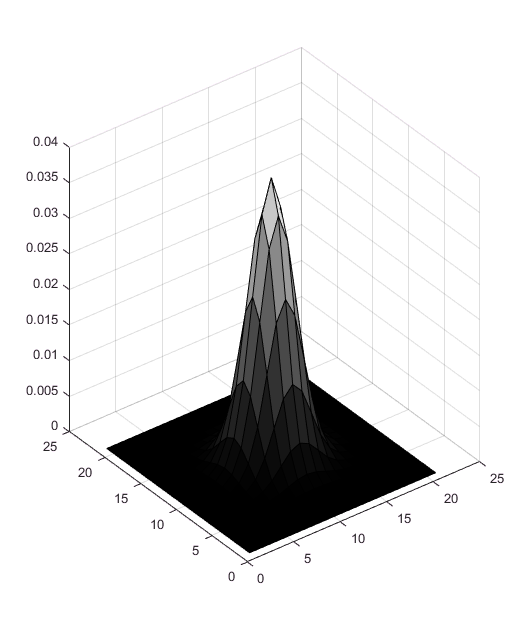

surf(filter);

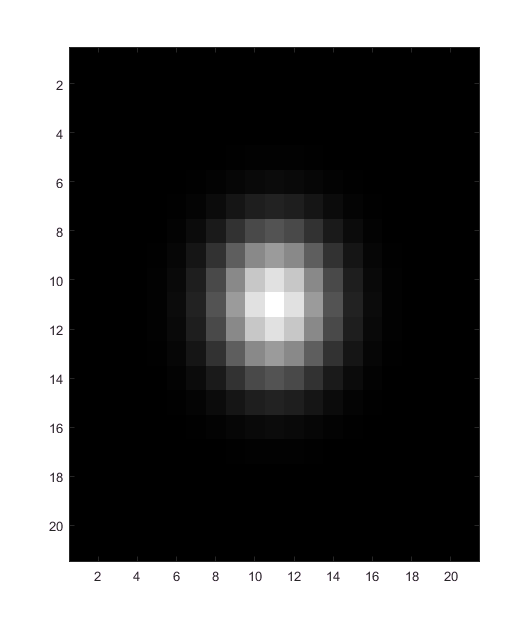

imagesc(filter);


% Apply it to remove noise
smoothed = imfilter(noisy_img,filter);
disp('smoothed image')

smoothed image


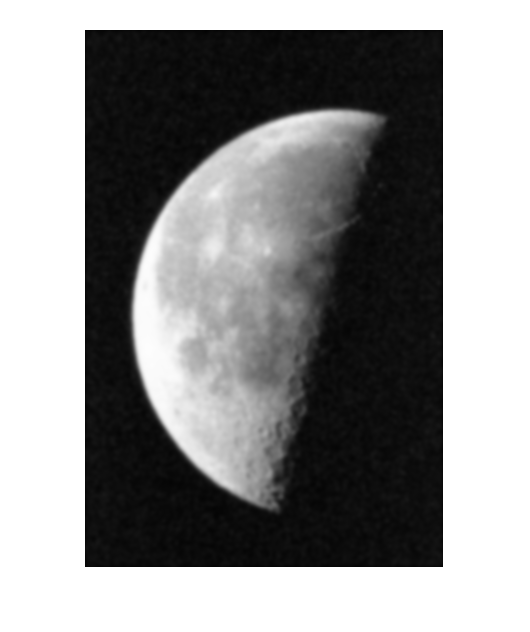

imshow(smoothed);